# **MQTT Loopback**

MQTT is an Ethernet communication protocol based on a publish-subscribe architecture. Clients connect with the broker and publish data for specific topics. The broker manages all the topics and passes the data to the other clients that subscribe to these topics. 

This example demonstrates the communication between one MQTT Client running on the Speedgoat real-time target machine and an external MQTT broker device.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

- "Runtime License File" that includes one MQTT Client license. Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

- An external MQTT broker device listening on IP address 192.168.10.50 TCP port 1883

Eclipse Mosquitto™ is an open source MQTT broker supporting different operating systems. The binary package for Windows is ready to use as a broker for the present example. Install and start the broker on a separate Windows computer by following the steps below:

- Download the Mosquitto MQTT broker from [https://mosquitto.org/download](https://mosquitto.org/download)

- Install the application to a folder that provides the needed write permission, *C:\Program Files\mosquitto*, for example

- Copy the configuration file *MQTT_Broker.conf* to a folder that provides the needed write permission, *C:\Data\MQTT_Broker.conf*, for example

- Open the *Network & Security *settings

- Under *Advanced network settings* click *Change adapter options*

- Double-click the adapter that you want to use for MQTT communication

- In the *Networking* tab, select *Internet Protocol Version 4 (TCP/IPv4)* and click *Properties*

- Select *Use the following IP address* and *Use the following DNS server addresses*

- Enter *192.168.10.50* and *255.255.255.0* in the fields *IP address* and *Subnet mask*

- Leave the other fields empty

- Confirm and close all opened dialogs in the *Network & Security *settings

- Open the *Command Prompt* app

- Navigate to the mosquitto installation folder by calling *cd C:\Program Files\mosquitto*

- Start the broker by calling *mosquitto -c C:\Data\MQTT_Broker.conf -v*

- The output of a properly started broker looks like this

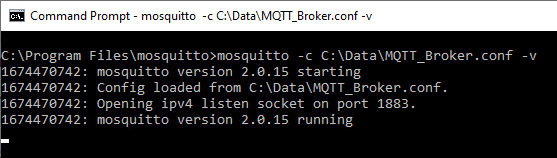

### Wiring of Target Machine

Use a CAT5 cable or newer to connect the target machine's Ethernet interface with the Ethernet adapter of the broker.

### Ethernet Configuration of the Client and Servers

Use the **Speedgoat Ethernet Configuration Tool** to assign the client's IP address to one unused Ethernet interface (onboard or IO71x/IO79x) on the target machine. 

The IP address assigned should be 192.168.10.1. The netmask for this local address is 255.255.255.0. 

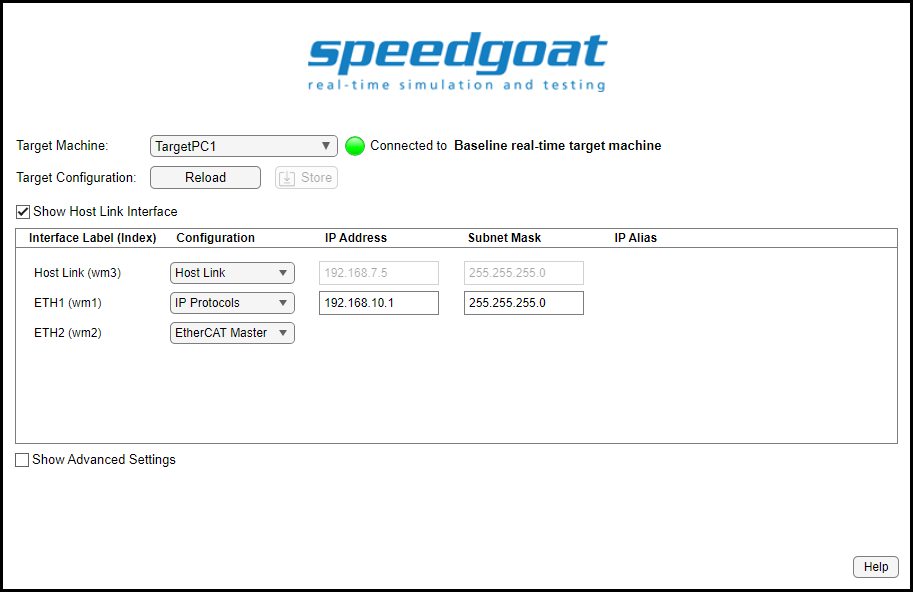

 
% Configure the Ethernet interface for the MQTT example
speedgoat.configureEthernet; % Open the Speedgoat Ethernet Configuration tool

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_MQTT_Loopback';
open_system(modelName);

### Model Description

The model sets up the communication for the MQTT Client and the remote MQTT Broker. The Station ID and Connection ID parameters are used to build up an internal relationship of the [Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mqtt_client_setup), [Connection](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mqtt_client_connection), [Publish](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mqtt_client_publish) and [Subscribe](https://www.speedgoat.com/help/slrt/page/io_main/refentry_mqtt_client_subscribe) blocks in the model. Both the Station ID and Connection ID are 0 as the model simulates only one MQTT client connected to one MQTT Broker. The MQTT client is represented to other devices in the network by the Client Identifier parameter in the Setup block.

Every 10 milliseconds, the client publishes data to the broker who passes this data back to the client as the client acts as a subscriber as well. The data is structured as follows:

- Counter signal of type uint32 for topic 'position', updated every 0.02 seconds

- Sine wave of type double for topic 'speed', updated every 0.01 seconds

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName);

% Set the stop time
tg.setStopTime(20);     % seconds

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,1);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;

s = sdiLatestRun.getSignalsByName('Position');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('Speed');
plotOnSubPlot(s,2,1,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,20,-100,20100]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,20,-110,110]);

The output is then visible in the Simulink Data Inspector (SDI). You should see the 4 signals the first server receives from the client and the 4 signals the client receives from the second server.

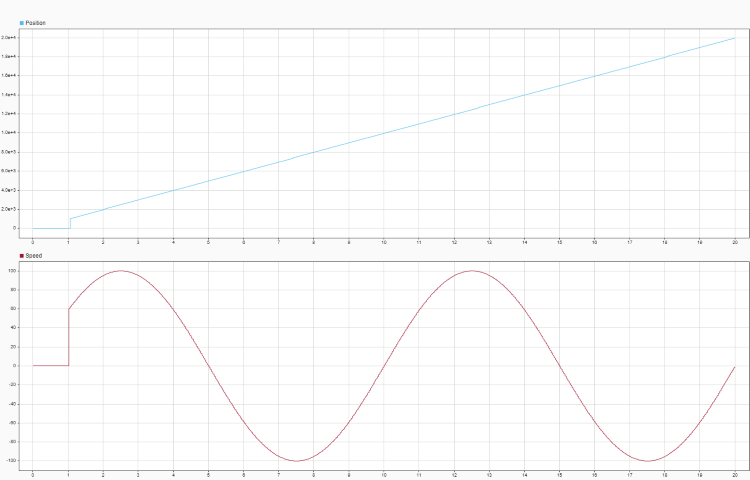

## Restore Target Machine Configuration

To restore the default configuration, you can simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_client)[MQTT Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mqtt_client)